# **Express the DCM in terms of Eigenaxis and quaternion parameters**

Summary:

- In PART-1 we'll express the DCM in terms of the Eigenaxis parameters

- In PART-2 we'll express the DCM in terms of the Quaternion parameters

# **Part 1 - **Derive the DCM in terms of Eigenaxis parameters

## Defining the Direction Cosine Matrix (DCM)

Say we have a vector $v$ and 2 frames $A$ and B.  The Direction Cosine Matrix(DCM) $^BR_A$ allows us to express the vector $v$ in components of the $B$ frame , given that we already know $v$ in components of the $A$ frame, ie:

- 
$$^Bv = {^BR_A}.^Av$$


## Defining the Eigenaxis parameters 

Recall how the Eigenaxis description for angular pose is defined by the 4 parameters and constraint

- 
$$E_X \;,E_Y \;,E_Z \;,\theta \;$$


- 
$$1\;\;=\;\;\;{E_X }^2 \;+\;\;\;{E_Y }^2 \;+\;\;{E_Z }^2 \;\;$$


sympref('AbbreviateOutput',false);

syms E_X E_Y E_Z theta
% assume(E_X,    'real')
% assume(E_Y,    'real')
% assume(E_Z,    'real')
% assume(theta,  'real')
% 
% assumeAlso(E_X^2 + E_Y^2 + E_Z^2 == 1)

## Deriving the DCM 

We'd like to express the DCM as a function of the Eigenaxis parameters, ie:

- 
$${^BR_A} = f(E_X,E_Y,E_Z,\theta)$$


To complete this derivation we'll look at a series of FRAME rotations

- 
$$A\Longrightarrow A\prime \Longrightarrow {A^{\prime } }^{\prime } \left(\theta \right)\;\Longrightarrow {\left\lbrack A\prime \right\rbrack }^{-1} =B$$


### Frame $A$ to $A^{\prime }$

The DCM relating these 2 frames is:

- 
$$^{A'}v = {^{A'}R_A}.^Av$$


We'll orientate frame $A\prime$ such that the $A\prime$ $X$-axis is in the SAME direction as the unit vector ${\left\lbrack E_{X,} \;,E_Y \;,E_Z \right\rbrack }_A$,  ie:

- 
$${\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack }_{A^{\prime } } \;\;=\;\;\left\lbrack \begin{array}{ccc}
E_X  & E_Y  & E_Z \\
K_{21}  & K_{22}  & K_{23} \\
K_{31}  & K_{32}  & K_{33} 
\end{array}\right\rbrack \ldotp {\left\lbrack \begin{array}{c}
E_X \\
E_Y \\
E_Z 
\end{array}\right\rbrack }_A$$


syms K_21  K_22  K_23  K_31  K_32  K_33

Ad_R_A = [  E_X,   E_Y,   E_Z;
           K_21,  K_22,  K_23;
           K_31,  K_32,  K_33; ]

$$Ad\_R\_A = \left(\begin{array}{ccc} E_{X} & E_{Y} & E_{Z}\\ K_{21} & K_{22} & K_{23}\\ K_{31} & K_{32} & K_{33} \end{array}\right)$$

### Frame $A^{\prime }$ to $A^{\prime \prime }$

The DCM relating these 2 frames is:

- 
$$^{A''}v = {^{A''}R_{A'}}.^{A'}v$$


The ${A^{\prime } }^{\prime }$ frame is created by rotating the $A^{\prime }$ frame around it's $X$-axis by $\theta$, ie:

- 
$${^{A''}R_{A'}} $$
  
$$=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \left(\theta \right) & \sin \left(\theta \right)\\
0 & -\sin \left(\theta \right) & \cos \left(\theta \right)
\end{array}\right\rbrack$$


Add_R_Ad = [  1,            0,           0;
              0,   cos(theta),  sin(theta);
              0,  -sin(theta),  cos(theta); ];  

### Frame $A^{\prime \prime }$ to $B$

To go from the ${A^{\prime } }^{\prime }$ frame to the $B$-frame, we'll do the **reverse** of ${^{A'}R_A}$

- 
$$^{B}v = {^{B}R_{A''}}.^{A''}v = [^{A'}R_A]^T \quad .  \quad{^{A''}v} $$


B_R_Add = Ad_R_A .' ;

### Frame $A$ to $B$

So putting this together we have:

- 
$$^{B}v = {^{B}R_{A}} \enspace . \enspace ^{A}v$$


- 
$$^{B}v \enspace = \enspace
\lbrack {^{B}R_{A''}} \enspace . \enspace
{^{A''}R_{A'}} \enspace . \enspace
{^{A'}R_{A}} \rbrack
\enspace . \enspace
{^A}v$$


- 
$$^{B}v \enspace = \enspace
\lbrack  [^{A'}R_A]^T \enspace . \enspace
{^{A''}R_{A'}} \enspace . \enspace
{^{A'}R_{A}} \rbrack
\enspace . \enspace
{^A}v$$


B_R_A = simplify( B_R_Add * Add_R_Ad * Ad_R_A )

$$B\_R\_A = \left(\begin{array}{ccc} {E_{X}}^{2}+\cos\left(\theta \right)\,{K_{21}}^{2}+\cos\left(\theta \right)\,{K_{31}}^{2} & K_{22}\,\left(K_{21}\,\cos\left(\theta \right)-K_{31}\,\sin\left(\theta \right)\right)+K_{32}\,\left(K_{31}\,\cos\left(\theta \right)+K_{21}\,\sin\left(\theta \right)\right)+E_{X}\,E_{Y} & K_{23}\,\left(K_{21}\,\cos\left(\theta \right)-K_{31}\,\sin\left(\theta \right)\right)+K_{33}\,\left(K_{31}\,\cos\left(\theta \right)+K_{21}\,\sin\left(\theta \right)\right)+E_{X}\,E_{Z}\\ K_{21}\,\left(K_{22}\,\cos\left(\theta \right)-K_{32}\,\sin\left(\theta \right)\right)+K_{31}\,\left(K_{32}\,\cos\left(\theta \right)+K_{22}\,\sin\left(\theta \right)\right)+E_{X}\,E_{Y} & {E_{Y}}^{2}+\cos\left(\theta \right)\,{K_{22}}^{2}+\cos\left(\theta \right)\,{K_{32}}^{2} & K_{23}\,\left(K_{22}\,\cos\left(\theta \right)-K_{32}\,\sin\left(\theta \right)\right)+K_{33}\,\left(K_{32}\,\cos\left(\theta \right)+K_{22}\,\sin\left(\theta \right)\right)+E_{Y}\,E_{Z}\\ K_{21}\,\left(K_{23}\,\cos\left(\theta \right)-K_{33}\,\sin\left(\theta \right)\right)+K_{31}\,\left(K_{33}\,\cos\left(\theta \right)+K_{23}\,\sin\left(\theta \right)\right)+E_{X}\,E_{Z} & K_{22}\,\left(K_{23}\,\cos\left(\theta \right)-K_{33}\,\sin\left(\theta \right)\right)+K_{32}\,\left(K_{33}\,\cos\left(\theta \right)+K_{23}\,\sin\left(\theta \right)\right)+E_{Y}\,E_{Z} & {E_{Z}}^{2}+\cos\left(\theta \right)\,{K_{23}}^{2}+\cos\left(\theta \right)\,{K_{33}}^{2} \end{array}\right)$$

So we now have our DCM  ${^{B}R_{A}} $  relating the $A$ and $B$ frames. We now need to simplify this into the form:

- 
$${^BR_A} = f(E_X,E_Y,E_Z,\theta)$$


Let's expand all expressions - it will help with the next step:

B_R_A = expand(B_R_A)

$$B\_R\_A = \left(\begin{array}{ccc} {E_{X}}^{2}+\cos\left(\theta \right)\,{K_{21}}^{2}+\cos\left(\theta \right)\,{K_{31}}^{2} & E_{X}\,E_{Y}+K_{21}\,K_{22}\,\cos\left(\theta \right)+K_{31}\,K_{32}\,\cos\left(\theta \right)+K_{21}\,K_{32}\,\sin\left(\theta \right)-K_{22}\,K_{31}\,\sin\left(\theta \right) & E_{X}\,E_{Z}+K_{21}\,K_{23}\,\cos\left(\theta \right)+K_{31}\,K_{33}\,\cos\left(\theta \right)+K_{21}\,K_{33}\,\sin\left(\theta \right)-K_{23}\,K_{31}\,\sin\left(\theta \right)\\ E_{X}\,E_{Y}+K_{21}\,K_{22}\,\cos\left(\theta \right)+K_{31}\,K_{32}\,\cos\left(\theta \right)-K_{21}\,K_{32}\,\sin\left(\theta \right)+K_{22}\,K_{31}\,\sin\left(\theta \right) & {E_{Y}}^{2}+\cos\left(\theta \right)\,{K_{22}}^{2}+\cos\left(\theta \right)\,{K_{32}}^{2} & E_{Y}\,E_{Z}+K_{22}\,K_{23}\,\cos\left(\theta \right)+K_{32}\,K_{33}\,\cos\left(\theta \right)+K_{22}\,K_{33}\,\sin\left(\theta \right)-K_{23}\,K_{32}\,\sin\left(\theta \right)\\ E_{X}\,E_{Z}+K_{21}\,K_{23}\,\cos\left(\theta \right)+K_{31}\,K_{33}\,\cos\left(\theta \right)-K_{21}\,K_{33}\,\sin\left(\theta \right)+K_{23}\,K_{31}\,\sin\left(\theta \right) & E_{Y}\,E_{Z}+K_{22}\,K_{23}\,\cos\left(\theta \right)+K_{32}\,K_{33}\,\cos\left(\theta \right)-K_{22}\,K_{33}\,\sin\left(\theta \right)+K_{23}\,K_{32}\,\sin\left(\theta \right) & {E_{Z}}^{2}+\cos\left(\theta \right)\,{K_{23}}^{2}+\cos\left(\theta \right)\,{K_{33}}^{2} \end{array}\right)$$

## Simplifying ${^{B}R_{A}} $

Recall that what we want to do is this:

- 
$${^BR_A} = f(E_X,E_Y,E_Z,\theta)$$


So? - So we need to somehow remove the $K_{\textrm{ij}}$ terms from our current expression for ${^BR_A} $

First, let's review the DCM $ {^{A'}R_A}$ .  Since it's a rotation matrix, we know that $I =  {^{A'}R_A}^T \enspace . \enspace {^{A'}R_A}$

I_mat = Ad_R_A.' * Ad_R_A

$$I\_mat = \left(\begin{array}{ccc} {E_{X}}^{2}+{K_{21}}^{2}+{K_{31}}^{2} & E_{X}\,E_{Y}+K_{21}\,K_{22}+K_{31}\,K_{32} & E_{X}\,E_{Z}+K_{21}\,K_{23}+K_{31}\,K_{33}\\ E_{X}\,E_{Y}+K_{21}\,K_{22}+K_{31}\,K_{32} & {E_{Y}}^{2}+{K_{22}}^{2}+{K_{32}}^{2} & E_{Y}\,E_{Z}+K_{22}\,K_{23}+K_{32}\,K_{33}\\ E_{X}\,E_{Z}+K_{21}\,K_{23}+K_{31}\,K_{33} & E_{Y}\,E_{Z}+K_{22}\,K_{23}+K_{32}\,K_{33} & {E_{Z}}^{2}+{K_{23}}^{2}+{K_{33}}^{2} \end{array}\right)$$

NOTE how we have 6 constraint equations that ALL involve the products of the terms $K_{\textrm{ij}}$, eg:  $K_{21} \ldotp K_{31}$. So? - So what I'd like to do is to first solve for these coupled products and then substitute into the DCM  ${^{B}R_{A}} $.  So let's first define our constraints:

EQ(1) = 1 == I_mat(1,1);
EQ(2) = 1 == I_mat(2,2);
EQ(3) = 1 == I_mat(3,3);

EQ(4) = 0 == I_mat(1,2);
EQ(5) = 0 == I_mat(1,3);
EQ(6) = 0 == I_mat(2,3);

Their are 3 additional constraints that are less obvious.  Since $ {^{A'}R_A}$ is a rotation matrix, then $  {^{A'}R_A}^T \enspace = \enspace   {^{A'}R_A}^{-1}$ and $ 1=det({^{A'}R_A})$ - see `bh_explore_ROT_inverse.mlx `.

EQ(7) = E_X == K_22*K_33 - K_23*K_32;
EQ(8) = E_Y == K_23*K_31 - K_21*K_33;
EQ(9) = E_Z == K_21*K_32 - K_22*K_31;

OK, let's start simplifying ${^{B}R_{A}} $ .Next Let's do a symbol substitution - using **CONSTRAINTS 7-9**

tmp_old = [(K_22*K_33),      (K_23*K_31),      (K_21*K_32)];
tmp_new = [(E_X + K_23*K_32),(E_Y + K_21*K_33),(E_Z + K_22*K_31)];
B_R_A   = subs(B_R_A, tmp_old, tmp_new)

$$B\_R\_A = \left(\begin{array}{ccc} {E_{X}}^{2}+\cos\left(\theta \right)\,{K_{21}}^{2}+\cos\left(\theta \right)\,{K_{31}}^{2} & \sin\left(\theta \right)\,\left(E_{Z}+K_{22}\,K_{31}\right)+E_{X}\,E_{Y}+K_{21}\,K_{22}\,\cos\left(\theta \right)+K_{31}\,K_{32}\,\cos\left(\theta \right)-K_{22}\,K_{31}\,\sin\left(\theta \right) & E_{X}\,E_{Z}-\sin\left(\theta \right)\,\left(E_{Y}+K_{21}\,K_{33}\right)+K_{21}\,K_{23}\,\cos\left(\theta \right)+K_{31}\,K_{33}\,\cos\left(\theta \right)+K_{21}\,K_{33}\,\sin\left(\theta \right)\\ E_{X}\,E_{Y}-\sin\left(\theta \right)\,\left(E_{Z}+K_{22}\,K_{31}\right)+K_{21}\,K_{22}\,\cos\left(\theta \right)+K_{31}\,K_{32}\,\cos\left(\theta \right)+K_{22}\,K_{31}\,\sin\left(\theta \right) & {E_{Y}}^{2}+\cos\left(\theta \right)\,{K_{22}}^{2}+\cos\left(\theta \right)\,{K_{32}}^{2} & \sin\left(\theta \right)\,\left(E_{X}+K_{23}\,K_{32}\right)+E_{Y}\,E_{Z}+K_{22}\,K_{23}\,\cos\left(\theta \right)+K_{32}\,K_{33}\,\cos\left(\theta \right)-K_{23}\,K_{32}\,\sin\left(\theta \right)\\ \sin\left(\theta \right)\,\left(E_{Y}+K_{21}\,K_{33}\right)+E_{X}\,E_{Z}+K_{21}\,K_{23}\,\cos\left(\theta \right)+K_{31}\,K_{33}\,\cos\left(\theta \right)-K_{21}\,K_{33}\,\sin\left(\theta \right) & E_{Y}\,E_{Z}-\sin\left(\theta \right)\,\left(E_{X}+K_{23}\,K_{32}\right)+K_{22}\,K_{23}\,\cos\left(\theta \right)+K_{32}\,K_{33}\,\cos\left(\theta \right)+K_{23}\,K_{32}\,\sin\left(\theta \right) & {E_{Z}}^{2}+\cos\left(\theta \right)\,{K_{23}}^{2}+\cos\left(\theta \right)\,{K_{33}}^{2} \end{array}\right)$$

Next Let's do a symbol substitution - using **CONSTRAINTS 1-3**

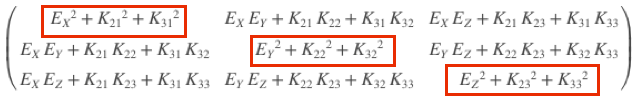

tmp_old = [(K_21*K_21),          (K_22*K_22),          (K_23*K_23)];
tmp_new = [(1 - E_X^2 - K_31^2), (1 - E_Y^2 - K_32^2), (1 - E_Z^2 - K_33^2)];
B_R_A   = subs(B_R_A, tmp_old, tmp_new);
B_R_A = simplify(B_R_A)

$$B\_R\_A = \left(\begin{array}{ccc} \cos\left(\theta \right)+{E_{X}}^{2}-{E_{X}}^{2}\,\cos\left(\theta \right) & E_{Z}\,\sin\left(\theta \right)+E_{X}\,E_{Y}+K_{21}\,K_{22}\,\cos\left(\theta \right)+K_{31}\,K_{32}\,\cos\left(\theta \right) & E_{X}\,E_{Z}-E_{Y}\,\sin\left(\theta \right)+K_{21}\,K_{23}\,\cos\left(\theta \right)+K_{31}\,K_{33}\,\cos\left(\theta \right)\\ E_{X}\,E_{Y}-E_{Z}\,\sin\left(\theta \right)+K_{21}\,K_{22}\,\cos\left(\theta \right)+K_{31}\,K_{32}\,\cos\left(\theta \right) & \cos\left(\theta \right)+{E_{Y}}^{2}-{E_{Y}}^{2}\,\cos\left(\theta \right) & E_{X}\,\sin\left(\theta \right)+E_{Y}\,E_{Z}+K_{22}\,K_{23}\,\cos\left(\theta \right)+K_{32}\,K_{33}\,\cos\left(\theta \right)\\ E_{Y}\,\sin\left(\theta \right)+E_{X}\,E_{Z}+K_{21}\,K_{23}\,\cos\left(\theta \right)+K_{31}\,K_{33}\,\cos\left(\theta \right) & E_{Y}\,E_{Z}-E_{X}\,\sin\left(\theta \right)+K_{22}\,K_{23}\,\cos\left(\theta \right)+K_{32}\,K_{33}\,\cos\left(\theta \right) & \cos\left(\theta \right)+{E_{Z}}^{2}-{E_{Z}}^{2}\,\cos\left(\theta \right) \end{array}\right)$$

Next Let's do a symbol substitution - using **CONSTRAINTS 4-6**

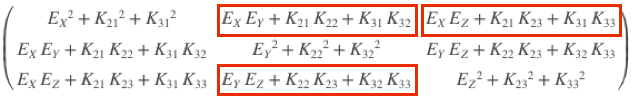

tmp_old = [(K_21*K_22),             (K_21*K_23),            (K_22*K_23)];
tmp_new = [( -E_X*E_Y - K_31*K_32), (-E_X*E_Z - K_31*K_33), (-E_Y*E_Z - K_32*K_33)];
B_R_A   = subs(B_R_A, tmp_old, tmp_new);
B_R_A = simplify(B_R_A)

$$B\_R\_A = \left(\begin{array}{ccc} \cos\left(\theta \right)+{E_{X}}^{2}-{E_{X}}^{2}\,\cos\left(\theta \right) & E_{Z}\,\sin\left(\theta \right)+E_{X}\,E_{Y}-E_{X}\,E_{Y}\,\cos\left(\theta \right) & E_{X}\,E_{Z}-E_{Y}\,\sin\left(\theta \right)-E_{X}\,E_{Z}\,\cos\left(\theta \right)\\ E_{X}\,E_{Y}-E_{Z}\,\sin\left(\theta \right)-E_{X}\,E_{Y}\,\cos\left(\theta \right) & \cos\left(\theta \right)+{E_{Y}}^{2}-{E_{Y}}^{2}\,\cos\left(\theta \right) & E_{X}\,\sin\left(\theta \right)+E_{Y}\,E_{Z}-E_{Y}\,E_{Z}\,\cos\left(\theta \right)\\ E_{Y}\,\sin\left(\theta \right)+E_{X}\,E_{Z}-E_{X}\,E_{Z}\,\cos\left(\theta \right) & E_{Y}\,E_{Z}-E_{X}\,\sin\left(\theta \right)-E_{Y}\,E_{Z}\,\cos\left(\theta \right) & \cos\left(\theta \right)+{E_{Z}}^{2}-{E_{Z}}^{2}\,\cos\left(\theta \right) \end{array}\right)$$

## Validate against the implementation:

import bh_rots_PKG.bh_eul_eigenaxis_CLS

OBJ = bh_eul_eigenaxis_CLS([E_X; E_Y; E_Z], theta);

assume(E_X,    'real')
assume(E_Y,    'real')
assume(E_Z,    'real')
assume(theta,  'real')
assumeAlso(1==E_X^2 + E_Y^2 + E_Z^2);

tmp_diff = simplify(B_R_A - OBJ.DCM_B_given_A)

$$tmp\_diff = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

## A few properties of the DCM defined using the Eigenaxis parameters:

simplify( sum(diag(B_R_A)) )

$$ans = 2\,\cos\left(\theta \right)+1$$

# **Part 2 - **Derive the DCM in terms of quaternion parameters

Recall the relationship between the quaternion and the Eigenaxis parameters

- 
$$\left\lbrack \begin{array}{c}
q_0 \\
q_X \\
q_Y \\
q_Z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\cos \left(\frac{\theta }{2}\right)\\
E_X \ldotp \sin \left(\frac{\theta }{2}\right)\\
E_Y \ldotp \sin \left(\frac{\theta }{2}\right)\\
E_Z \ldotp \sin \left(\frac{\theta }{2}\right)
\end{array}\right\rbrack$$
    

where:

- 
$$\;\left(\;1\;\;=\;\;\;{E_X }^2 \;+\;\;\;{E_Y }^2 \;+\;\;{E_Z }^2 \;\right)\;\;\;\;\;\textrm{and}\;\;\;\;\left(\;1\;\;=\;\;{q_0 }^2 +\;\;\;\;{q_X }^2 \;+\;\;\;{q_Y }^2 \;+\;\;{q_Z }^2 \;\right)$$


NOTE also the following relationships:

- 
$$\cos^2 \left(\frac{\theta }{2}\right)={q_0 }^2$$


- 
$$\sin^2 \left(\frac{\theta }{2}\right)\ldotp \left({E_X }^2 \;+\;\;\;{E_Y }^2 \;+\;\;{E_Z }^2 \right)={{\;\;q}_X }^2 \;+\;\;\;{q_Y }^2 \;+\;\;{q_Z }^2 \;$$


- 
$$\sin^2 \left(\frac{\theta }{2}\right)=\;{{\;\;q}_X }^2 \;+\;\;\;{q_Y }^2 \;+\;\;{q_Z }^2 \;\;=\;1-{q_0 }^2 \;$$


- 
$$\cos \left(\theta \right)=\cos^2 \left(\frac{\theta }{2}\right)-\;\;\sin^2 \left(\frac{\theta }{2}\right)\;\;=\;2\ldotp \cos^2 \left(\frac{\theta }{2}\right)\;-1$$


- 
$$\cos \left(\theta \right)={{2q}_0 }^2 -1\;$$


- 
$$\sin \left(\theta \right)=2\ldotp \cos \left(\frac{\theta }{2}\right)\ldotp \sin \left(\frac{\theta }{2}\right)=2\ldotp q_0 \;\ldotp \sqrt{1-{q_0 }^2 }\;$$


So if we already know the DCM in terms of the Eigenaxis parameters, it's a simple variable substituition to define the DCM in terms of the quaternions parameters:

- 
$$\cos \left(\theta \right)={{2q}_0 }^2 -1\;\;$$


- 
$$E_X =\frac{q_X }{\sin \left(\frac{\theta }{2}\right)}\;\;=\;\;\;\frac{q_X }{\sqrt{1-{q_0 }^2 }}$$


- 
$$E_Y =\frac{q_Y }{\sin \left(\frac{\theta }{2}\right)}\;\;=\;\;\;\frac{q_Y }{\sqrt{1-{q_0 }^2 }}$$


- 
$$E_Z =\frac{q_Z }{\sin \left(\frac{\theta }{2}\right)}\;\;=\;\;\;\frac{q_Z }{\sqrt{1-{q_0 }^2 }}$$


syms q_0 q_X q_Y q_Z

assume(q_0,    'real')
assume(q_X,    'real')
assume(q_Y,    'real')
assume(q_Z,    'real')
assumeAlso( 1 == q_0^2 + q_X^2 + q_Y^2 + q_Z^2)

tmp_sh2 = sqrt(1-q_0^2);
tmp_old = [ cos(theta),    sin(theta),     E_X,           E_Y,           E_Z ];
tmp_new = [(2*q_0^2 - 1), (2*q_0*tmp_sh2),(q_X/tmp_sh2), (q_Y/tmp_sh2), (q_Z/tmp_sh2) ];

my_q_DCM = simplify(  subs(B_R_A, tmp_old, tmp_new)  )

$$my\_q\_DCM = \left(\begin{array}{ccc} -2\,{q_{Y}}^{2}-2\,{q_{Z}}^{2}+1 & 2\,q_{0}\,q_{Z}+2\,q_{X}\,q_{Y} & 2\,q_{X}\,q_{Z}-2\,q_{0}\,q_{Y}\\ 2\,q_{X}\,q_{Y}-2\,q_{0}\,q_{Z} & -2\,{q_{X}}^{2}-2\,{q_{Z}}^{2}+1 & 2\,q_{0}\,q_{X}+2\,q_{Y}\,q_{Z}\\ 2\,q_{0}\,q_{Y}+2\,q_{X}\,q_{Z} & 2\,q_{Y}\,q_{Z}-2\,q_{0}\,q_{X} & -2\,{q_{X}}^{2}-2\,{q_{Y}}^{2}+1 \end{array}\right)$$

## Validate against the implementation:

import bh_rots_PKG.bh_quat_rot_CLS

OBJ_quat_rot = bh_quat_rot_CLS();

imp_my_q_DCM = OBJ_quat_rot.calc_dcm_from_q( [q_0; q_X; q_Y; q_Z] );

simplify(my_q_DCM - imp_my_q_DCM)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

## Note the following about the DCM:

Recall the DCM expressed in terms of the quaternion parameters:

my_q_DCM

$$my\_q\_DCM = \left(\begin{array}{ccc} -2\,{q_{Y}}^{2}-2\,{q_{Z}}^{2}+1 & 2\,q_{0}\,q_{Z}+2\,q_{X}\,q_{Y} & 2\,q_{X}\,q_{Z}-2\,q_{0}\,q_{Y}\\ 2\,q_{X}\,q_{Y}-2\,q_{0}\,q_{Z} & -2\,{q_{X}}^{2}-2\,{q_{Z}}^{2}+1 & 2\,q_{0}\,q_{X}+2\,q_{Y}\,q_{Z}\\ 2\,q_{0}\,q_{Y}+2\,q_{X}\,q_{Z} & 2\,q_{Y}\,q_{Z}-2\,q_{0}\,q_{X} & -2\,{q_{X}}^{2}-2\,{q_{Y}}^{2}+1 \end{array}\right)$$

Note the following properties about the DCM

q_sq = 0.25 * [  (1 + my_q_DCM(1,1) + my_q_DCM(2,2) + my_q_DCM(3,3) );
                 (1 + my_q_DCM(1,1) - my_q_DCM(2,2) - my_q_DCM(3,3) );
                 (1 - my_q_DCM(1,1) + my_q_DCM(2,2) - my_q_DCM(3,3) );
                 (1 - my_q_DCM(1,1) - my_q_DCM(2,2) + my_q_DCM(3,3) );  ]

$$q\_sq = \left(\begin{array}{c} -{q_{X}}^{2}-{q_{Y}}^{2}-{q_{Z}}^{2}+1\\ {q_{X}}^{2}\\ {q_{Y}}^{2}\\ {q_{Z}}^{2} \end{array}\right)$$

where clearly:

- 
$$\left(\;{q_0 }^2 \;\;=\;1\;-\;\;{q_X }^2 -\;\;\;{q_Y }^2 -\;\;{q_Z }^2 \;\right)$$


So ? So if we are given a DCM we can extract the quaternion parameters using the following approach:

- determine the largest term from q_sq

- Then ADD together appropiate terms to isolate the remaining quaternion parameters

For example  IFF  ${q_0 }^2$ was the maximum, then: